# Script: Importador de Mapas en Blanco y Negro

Permite importar imágenes representando mapas (Imágenes en blanco y negro. Obstáculos en negro) y retornar los vértices del polígono a emplear. Resultados y tiempo de procesado puede llegar a variar según la complejidad del ambiente. También se recomienda obviar obstáculos redondos, aunque el sistema si es capaz de manejarlos. El detalle es que probablemente los dibujará "pixeleados" o escalonados.

### Evitar Lecturas Redundantes de la Misma Imagen

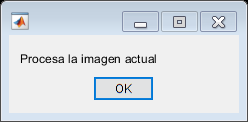

clear;

% Se lee la imagen del mapa
PathImagen = "Jabandzic 1.png";

% Se busca la imagen en el directorio actual
if isfile(PathImagen)
    ImagenMapa = imread(PathImagen);
    
% Si no está en el path actual, se busca en los mapas guardados
elseif isfile(".\Mapas\Imágenes\" + PathImagen)
    ImagenMapa = imread(".\Mapas\Imágenes\" + PathImagen);
    
% Si no se encuentra en ninguna ruta, se retorna un error.
else
    error("Error: No existe la imagen especificada en el directorio actual");
end

% Se convierte la imagen a blanco y negro si la imagen tiene una tercera
% dimensión (Está a color).
if ndims(ImagenMapa) == 3
    ImagenMapa = rgb2gray(ImagenMapa);
end

% Se extrae el nombre de la imagen (Sin ruta o extensión)
[~,NombreImagen,~] = fileparts(PathImagen);

% Directorio conteniendo las imágenes 
Directorio = ".\Mapas\Imágenes\";
DatosArchivos = [dir(fullfile(Directorio,'*.png')) ; dir(fullfile(Directorio,'*.jpg'))];
SSIMVal = zeros(numel(DatosArchivos),1);

% Se revisa cada elemento dentro de la carpeta de "imágenes" de mapas
for i = 1:numel(DatosArchivos)
    
    % Se abre cada archivo y 
    F = fullfile(Directorio,DatosArchivos(i).name);
    I = imread(F);
    
    % Si el tamaño de dos imágenes coincide, se saca el índice de similitud
    % directamente
    
    if size(ImagenMapa,1) == size(I,1) && size(ImagenMapa,2) == size(I,2)
        SSIMVal(i) = ssim(I,ImagenMapa);
        
    % Si el tamaño de las dos imágenes no coincide, primero se redimensiona
    % la imagen guardada para que coincida con la que se abrió.
    else
        I = imresize(I,[size(ImagenMapa,1), size(ImagenMapa,2)]);
        SSIMVal(i) = ssim(I,ImagenMapa);
    end
end

[Similitud,MejorCoincidencia] = max(SSIMVal);

% Si la mejor coincidencia con la imagen a analizar está por encima del 90%. 
if Similitud > 0.9
    Respuesta = questdlg('Mapa actual similar a uno previamente procesado. ¿Desea utilizar los datos del mapa previo?',...
                         'Importador de Mapas','Si','No','No');
    
    switch Respuesta
        case "Si"
            PathCoincidencia = DatosArchivos(MejorCoincidencia).name;
            [~,NombreCoincidencia,~] = fileparts(PathCoincidencia);
            load(".\Mapas\Vertices\" + NombreCoincidencia + ".mat");
            %VerticesClean = VerticesClean;
            msgbox("Datos de mapa cargados");
            ProcesarImagen = 0;
            
        case "No"
            msgbox("Procesa la imagen actual");
            ProcesarImagen = 1;
            
        otherwise
            msgbox("Error: Respuesta no válida");
            ProcesarImagen = 0;
    end

else
    msgbox("Procesando la imagen actual");
    ProcesarImagen = 1;
end

### Lectura de Imagen y Extracción de Bordes

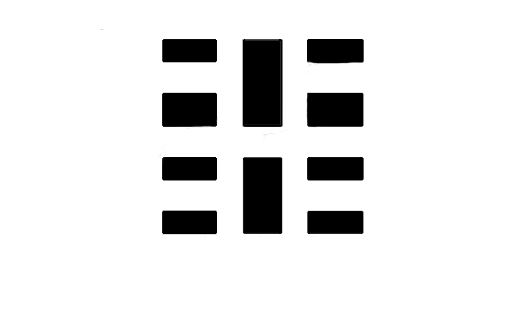

% Visualización de la imagen
figure(1); clf; hold on;
imshow(ImagenMapa);

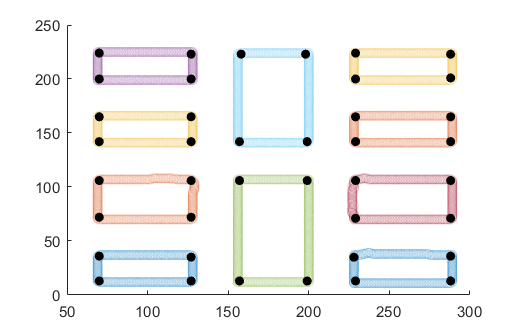

% Thresholding para limpiar cualquier mancha en escala de grises
Mapa = ImagenMapa < 250;

% Celda conteniendo en cada uno de sus elementos un conjunto de coordenadas
% que definen los diferentes obstáculos o elementos en el mapa.
[Bordes,~,NoBordes,EsquinasCercanas] = bwboundaries(Mapa);

% Número de puntos que debe tener un borde para ser considerado válido
ThresholdPuntos = 100;

% Inicialización de variables para el for-loop
Puntos = [];
i = 1;

% Visualización de los bordes. No se utiliza un for-loop porque el número
% de loops depende del NoBordes y el número de bordes cambia de forma
% dinámica conforme se limpia la detección.
figure(2); clf; hold on;
while i <= numel(Bordes)
    
    % Se grafican los bordes con más de "ThresholdPuntos"
    if size(Bordes{i},1) > ThresholdPuntos
        Puntos = [Puntos; Bordes{i}];
        scatter(Bordes{i}(:,2),Bordes{i}(:,1),'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
        i = i + 1;
    
    % Se eliminan los bordes con menos de "ThresholdPuntos" para eliminar
    % bordes "ruidosos" o insignificantes.
    else
        Bordes(i) = [];
        NoBordes = NoBordes - 1;
    end
    
end

% Existe la posibilidad de que algunos mapas consistan de "paredes con
% diferentes formas". En estos casos, los bordes exteriores del mapa no se
% detectarán por estar pegados a los límites de la imagen. Para prevenir
% que no se detecten, se le agrega un margen de blanco, alrededor de la
% imagen.
PadSize = 3;
PaddedImagenMapa = padarray(ImagenMapa,[PadSize PadSize],255,'both');

% Detección de las esquinas de los polígonos. 
% Matlab recomienda utilizar métodos de la Computer Vision Toolbox, pero
% al probarlas no resultaron tan útiles.
%   - detectHarrisFeatures() no detecta esquinas en la parte de la imagen
%     que esta pegada a arriba.
%   - detectMinEigenFeatures() requiere de un parámetro adicional, el
%     número de detecciones "fuertes" a filtrar, lo cual hace menos
%     automático el proceso.
%
% A las esquinas obtenidas se les resta el tamaño del padding para
% re-alinear los puntos con las coordenadas de los puntos extraidos 
% previamente.
Esquinas = corner(PaddedImagenMapa) - [PadSize PadSize];

% Se mide la similitud entre los puntos obtenidos en "bwboundaries()" y en
% "corner()" obteniendo la distancia euclideana de cada esquina a los "Puntos"
% y luego determinando si las distancias son menores al threshold de error.
ThresholdError = 2;
[~,DistsError] = dsearchn([Puntos(:,2) Puntos(:,1)],Esquinas);

% Si el número de esquinas con un error mayor al threshold de error es
% mayor al número de errores máximo soportado, se ignoran las esquinas y se
% supone que las esquinas son iguales a los puntos retornados por "bwboundaries()".
NoErrores = 4;
if sum(DistsError > ThresholdError) > NoErrores
    Esquinas = [Puntos(:,2) Puntos(:,1)];
end

scatter(Esquinas(:,1),Esquinas(:,2),'black','filled');

### Identificación de la Secuencia de los Puntos (Preparación de Datos)

Lo que se desea es tomar el montón de puntos que devuelve bwboundaries() y ordenarlos de manera secuencial para que al graficarlos usando polyshape, no existan errores por lados entrecruzados o vértices repetidos. Esto se consigue solucionando el problema del "travelling salesman". Se ofrecen dos alternativas de solución, ambas basadas en diferentes propuestas dadas por Matlab.

#### Alternativa 1: Optimización Usando intlinprog()

Forma bastante lenta por el uso de una matriz "sparse" a la cual le es asignado una cantidad cada vez más grande de datos. En total toma casi 4 minutos para obstáculos grandes, aunque para obstáculos pequeños es mucho más eficiente que la alternativa 2.

% Basado en:
% https://www.mathworks.com/help/optim/ug/travelling-salesman-problem.html

NoPuntos = size(Puntos,1);
IndxCombPosibles = nchoosek(1:NoPuntos, 2);

% Coordenadas de puntos
X = Puntos(:,2);
Y = Puntos(:,1);

% Básicamente nos ahorra el hacer sqrt(X.^2 + Y.^2)
DistsEntrePuntos = hypot(X(IndxCombPosibles(:,1)) - X(IndxCombPosibles(:,2)), Y(IndxCombPosibles(:,1)) - Y(IndxCombPosibles(:,2)));

% Cantidad de "distancias entre puntos"
NoDistancias = size(DistsEntrePuntos,1);

% Matriz de restricciones: Restricciones lineales para establecer que cada
% punto tiene dos distancias asociadas porque este consiste de un polígono
% cerrado (De cada punto debe salir y entrar una línea).
Aeq = spalloc(NoPuntos,NoDistancias,NoPuntos*(NoPuntos-1));

% Creación de "Progress Bar" para ver como va el procesado de puntos
ProgressBar = waitbar(0,'Procesando Puntos...');

% Esta sección puede llegar a tardar bastante. Porfavor paciencia.
for i = 1:NoPuntos
    CualIndx = (IndxCombPosibles == i);     % Encontrar distancias que incluyan el punto "i"
    CualIndx = sparse(sum(CualIndx,2));     % Incluir distancias donde el punto "i" es un extremo
    Aeq(i,:) = CualIndx';                   % Incluir en la matriz de restricciones
    waitbar(i / NoPuntos);
end

close(ProgressBar);

Beq = 2*ones(NoPuntos,1);

% Extremos Binarios: Todas las variables de decisión son binarias. La
% variable "intcon" a un vector con igual longitud al número de distancias.
% Ahora se coloca un "lower bound" de 0 y un "upper bound" de 1 para todos
% los elementos del array.
intcon = 1:NoDistancias;
LowerBnd = zeros(NoDistancias,1);
UpperBnd = ones(NoDistancias,1);

Esta parte del código puede llegar a fallar o generar errores a veces. Probar varias veces. Al consistir de un método basado en métodos estocásticos (Optimizador dependiente de parámetros aleatorios) algunas veces no se pueden llegar a obtener los resultados deseados.

% Optimización usando "intlinprog": El problema está listo para ser
% solucionado. Para eliminar el output por iteración, el setting de
% "Display" == "Off".
Options = optimoptions('intlinprog','Display',"off");
[X_tsp,costopt,exitflag,output] = intlinprog(DistsEntrePuntos,intcon,[],[],Aeq,Beq,LowerBnd,UpperBnd,Options);

X_tsp = logical(round(X_tsp));

#### Alternativa 2: Optimización Usando el Solver

Esta solución dura aproximadamente 1 minuto con 45 segundos para mapas de tamaño grande. Si el número de obstáculos es mayor o la geometría es más compleja, puede llegar a durar más. Recomendable para todo uso, aunque puede llegar a tardar más que la alternativa 1 (Por un poco) para mapas de complejidad baja.

% Basado en:
% https://www.mathworks.com/help/optim/examples/travelling-salesman-problem.html

NoPuntos = size(Puntos,1);
IndxCombPosibles = nchoosek(1:NoPuntos, 2);
Grafo = graph(IndxCombPosibles(:,1),IndxCombPosibles(:,2));

% Coordenadas de puntos
X = Puntos(:,2);
Y = Puntos(:,1);

% Básicamente nos ahorra el hacer sqrt(X.^2 + Y.^2)
DistsEntrePuntos = hypot(X(IndxCombPosibles(:,1)) - X(IndxCombPosibles(:,2)), Y(IndxCombPosibles(:,1)) - Y(IndxCombPosibles(:,2)));
LargoDist = length(DistsEntrePuntos);

% Creación de variables y problema
tsp = optimproblem;
Conexiones = optimvar('trips',LargoDist,1,'Type','integer','LowerBound',0,'UpperBound',1);

% Incluir la función objetivo en el problema
tsp.Objective = DistsEntrePuntos'*Conexiones;

% Creación de "Progress Bar" para ver como va el procesado de puntos
ProgressBar = waitbar(0,'Procesando Puntos...');

% Restricciones
Constr2Conex = optimconstr(NoPuntos,1);
for i = 1:NoPuntos
    
    % Identifica las conecciones asociadas con este punto
    whichIndx = outedges(Grafo,i);
    Constr2Conex(i) = sum(Conexiones(whichIndx)) == 2;
    
    % Actualización de barra de progreso
    waitbar(i / NoPuntos);
end

close(ProgressBar);
tsp.Constraints.Constr2Conex = Constr2Conex;

% Solucionar problema inicial
Options = optimoptions('intlinprog','Display','off');
tspsol = solve(tsp,'options',Options);

% Extracción de solución
X_tsp = logical(round(tspsol.trips));

### Re-ordenamiento de las coordenadas usando los resultados previos.

El optimizador nos retorna que puntos están probablemente unidos entre si, este es el vector de "Parejas": En la primera columna está el índice de un punto y en la segunda columna está el índice del punto que más probablemente está conectado con este.

% Se extraen las parejas "conectadas" resueltas por el optimizador
Parejas = [IndxCombPosibles(X_tsp,1) IndxCombPosibles(X_tsp,2)];
NoPuntos = size(Parejas,1);

% Basado en este post: 
% https://www.mathworks.com/matlabcentral/answers/112226-sorting-a-list-of-edges

% Array con los índices ordenados de la siguiente manera:
% [1 4; 4 7; 7 10; 10 3; 3 6; 6 8]. 
% En otras palabras, el array expresa una "cadena de conexión" (Punto 1 conectado
% con punto 4, punto 4 conectado con 7, punto 7 conectado con 10, etc.)
VerticeSort = zeros(NoPuntos,2);

% Punto del que se parte el ordenamiento
VerticeSort(1,:) = Parejas(1,:);

% Vector binario que indica cuales son los puntos ya visitados. La posición
VerticeVisit = zeros(NoPuntos,1);
VerticeVisit(1) = 1;

% Inicialización de número objetos
NoObjeto = 1;
OrdenObjetos = cell(NoBordes,1);
i = 2;

while i <= (NoPuntos)
    
     % Indice del punto actual del que se buscará su pareja (Valor en la
     % segunda columna de la fila previa del array de vértices ordenados).
     inod = VerticeSort(i-1,2);
     
     % Se obtienen todos los puntos que aún no se han colocado en la lista
     % "VerticeSort" y por lo tanto, consisten de los puntos que aún deben
     % interconectarse con otros puntos.
     iedg = find(VerticeVisit == 0);
     
     % Encontrar la fila (idx) y columna (jdx) donde aparece de nuevo el
     % punto actual a conectar (inod) dentro de la lista de parejas sin
     % interconectar (Parejas(iedg,:)).
     [idx,jdx] = find(Parejas(iedg,:) == inod);
     
     % El punto a interconectar se agrega en la columna 1 de la fila "i"
     % del array de vertices ordenados. Debemos encontrar el valor al que
     % está conectado o el valor en la segunda columna.
     VerticeSort(i,1) = inod;
     
     % Si no hay puntos sin interconectar que conecten con el punto actual
     % se asume que se llegó al final de los puntos que pertenecen al
     % objeto actual.
     if isempty(idx) || isempty(jdx)
         OrdenVerticesObjeto = VerticeSort(1:i-1,:);
         [~,IndParejasNorm] = intersect(Parejas,OrdenVerticesObjeto,"rows");
         [~,IndParejasFlip] = intersect(Parejas,fliplr(OrdenVerticesObjeto),"rows");
         
         IndAEliminar = [IndParejasNorm ; IndParejasFlip];
         
         Parejas(IndAEliminar,:) = [];      % Se eliminan los puntos presentes en el objeto completado
         NoPuntos = size(Parejas,1);        % Se actualiza al número de puntos total
         VerticeSort = zeros(NoPuntos,2);   % Se reinicia el vector de puntos ordenados
         VerticeSort(1,:) = Parejas(1,:);   
         VerticeVisit = zeros(NoPuntos,1);  % Se reinicia el vector de puntos visitados
         VerticeVisit(1) = 1;
         i = 2;                             % Se reinicia la cuenta de i
         
         OrdenObjetos{NoObjeto} = OrdenVerticesObjeto;
         NoObjeto = NoObjeto + 1;
         continue;                          % Se brinca de una vez a la siguiente iteración del while-loop
     end
     
     % Si la columna donde aparece el punto actual a conectar es la primera
     % columna del array "Parejas", el punto conectado a este consistirá
     % del número en la segunda columna de las "Parejas" no conectadas.
     if jdx == 1
         VerticeSort(i,2) = Parejas(iedg(idx),2); 
     
     % Si la columna donde aparece el punto actual es la segunda columna de
     % "Parejas" entonces se agrega el valor en la columna 1.
     else
         VerticeSort(i,2) = Parejas(iedg(idx),1);
     end
     
     % Actualizar la lista de puntos interconectados
     VerticeVisit(iedg(idx)) = 1;
     i = i + 1;
     
end

% Por el funcionamiento del loop anterior, existe la posibilidad que el
% último objeto no se guarde en "OrdenObjetos" entonces a continuación se
% guarda manualmente este elemento.
if ~isempty(VerticeSort(1:i-1,:))
    OrdenObjetos{NoObjeto} = VerticeSort(1:i-1,:);
end

% Se reordenan los puntos de cada elemento según el orden deducido
% previamente
Vertices = cell(NoBordes,1);
for i = 1:numel(OrdenObjetos)
    Orden = OrdenObjetos{i}(:,1);
    Vertices{i} = [Puntos(Orden,2) Puntos(Orden,1)];
end


### Ordenando las Esquinas

Se toman todas las esquinas detectadas por la rutina corner() y luego se ordenan según el orden de los puntos ordenados más cercanos obtenidos previamente (Ahora contenidos en "Vertices").

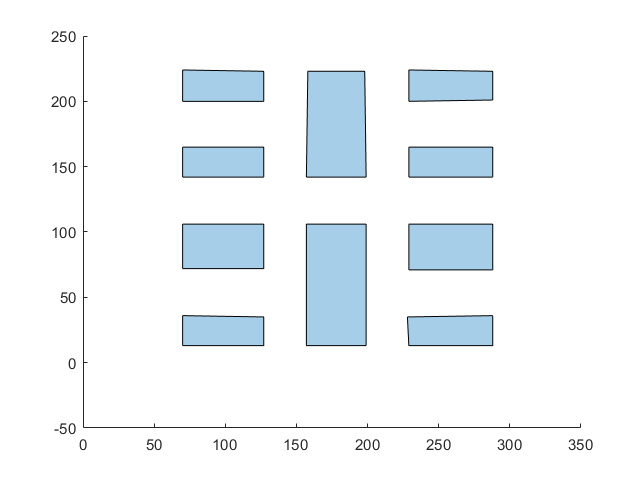

VerticesClean = [];

% Distancia en pixeles a la que debería de estar una esquina para ser
% considerada "cercana" a un punto.
ThresholdDist = 3;                          

for i = 1:numel(Vertices)
    % Se obtiene
    %   - PuntosMasCercanos: Indices de "Vertices" que están más cercano a las
    %     esquinas actuales.
    %   - Distancias: Las distancias a dichos puntos más cercanos.
    [PuntosMasCercanos,Distancias] = dsearchn(Vertices{i},Esquinas);
    
    % Indice de los puntos más cercanos del objeto "i" que coinciden con las 
    % actuales esquinas.
    EsquinasCercanas = PuntosMasCercanos(Distancias < ThresholdDist,:);
    EsquinasUtiles = Esquinas(Distancias < ThresholdDist,:);
    
    % Se ordenan las esquinas encontradas en orden ascendente para que al
    % conectar los puntos usando un polígono, no existan cruces de líneas.
    [~,IndEsquinasAscen] = sort(EsquinasCercanas,'ascend');
    
    % Extracción de los vértices del objeto actual en orden correcto para
    % que puedan convertirse debidamente en un polígono
    VerticesObjeto = EsquinasUtiles(IndEsquinasAscen,:);
    VerticesClean = [VerticesClean ;
                     VerticesObjeto;
                     NaN NaN];
end

% Gráfica de los vértices finales usando "plot". Si los vértices están bien
% definidos entonces plot generará un polígono cerrado.
figure(3); clf; hold on; 
Poly = polyshape(VerticesClean(:,1), VerticesClean(:,2));
plot(Poly);

### Guardando Datos

% Se guardan la imagen procesada y los vértices extraídos
imwrite(ImagenMapa, ".\Mapas\Imágenes\" + PathImagen);
save(".\Mapas\Vertices\" + NombreImagen + ".mat","VerticesClean");